# **BONE RUGOSITY ANALYSIS**

The roughness of a bone interface is characterized by the Root Mean Square (RMS) of the height of the rugosity at the endosteum of the bone, noted as Rq, and the correlation length, which characterizes the roughness horizontally.

This script enables the computation of the RMS for a bone. The height is computed relative to a parabola that fits the boundary of the bone. The images used are X-ray images of slices from five ex-vivo bones.

%% Create bone structure 
% bones = {{'227G' 1270 1793}; {'245D' 470 1861}; {'251G' 761 2125}; {'271G' 1590 2954}};
bones = {'271G' '267G' '251G' '245D' '227G'};
min_slices = [1270 0 470 761 1590];
max_slices = [1793 0 1861 2125 2954];
T = table(min_slices', max_slices', 'VariableNames', {'min_slice', 'max_slice'}, 'RowNames', bones);

% Get bone

`Select the bone : `

bone = '227G'

bone = '227G'

dirname = ['~/Documents/BoneRugosity/RMS/', bone, '/'];

min_slice = T{bone, 'min_slice'};
max_slice = T{bone, 'max_slice'};

`Select the slice :`

num_slice = 1590

num_slice = 1590


file = ['SAMPLE_', bone, '_SLICE_', int2str(num_slice), '.bmp']; 
filename = [dirname, file];

% LOAD IMAGE OF THE SLICE
bone_bmp = imread(filename); 


### I. BINARIZATION OF THE IMAGE 

The image is binarize with an automatic threshold. 

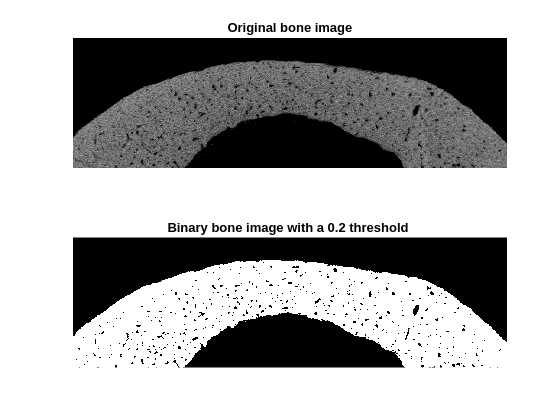

% THRESHOLD TO CONVERT TO BINARY IMAGE
threshold = graythresh(bone_bmp);                   % Find an automatic threshold
binary_image = imbinarize(bone_bmp, threshold);

figure,
subplot(2,1,1);
imshow(bone_bmp); 
title('Original bone image');
subplot(2,1,2);
imshow(binary_image); 
title(sprintf('Binary bone image with a %0.1f threshold ', threshold));

### II. SELECTION OF THE ENDOSTEUM BOUNDARY 

In order to obtain the heigth only of the porosity of the endosteum, the limits of the endost need to be indicated. 

`Input or update the limits of the endosteum :` 

 
binary_disp = binary_image *255;
X = boundary(:, 1);
Y = boundary(:, 2);
figure

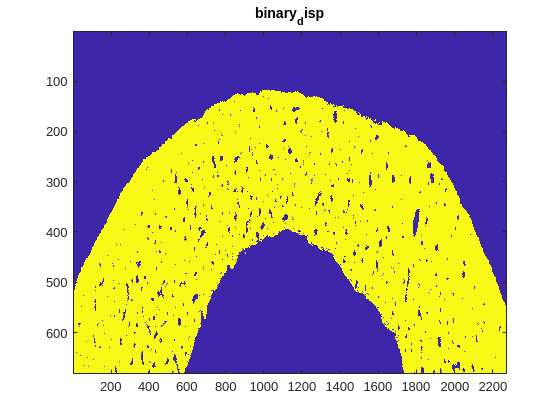

% Create image of binary_disp
im2 = image(binary_disp);

% Add title
title("binary_disp")

% Find change points
changeIndices = ischange(boundary,"Threshold",2.5);
% imshow(binary_image);
% hold on;
% plot(boundary(:, 1), boundary(:,2), 'o');
% Delimitation of the endost using getpts.
% [x1,y1] = getpts; 
% [x2,y2] = getpts; 

Double-clic on each sides of the endost in order to define its manually its limits. 


figure
% imshow(binary_image);
% hold on;
% plot(boundary(:, 1), boundary(:,2), 'o');
% Delimitation of the endost using getpts.
% [x1,y1] = getpts; 
% [x2,y2] = getpts; 

xy = [x1 y1; x2 y2];


% The limitation of the endost need to be founded for each image of the
% bone
% [lim, ~] = dsearchn(boundary,xy);   % Search the closest point to the manually selected limit of the endost
% boundary_endost = boundary(min(lim): max(lim), :);
% 
% % Plot to verify for the first image
% if nargin == 1
%     imshow(binary_image);
%     hold on;
%     plot(boundary_endost(:, 1), boundary_endost(:, 2), 'r', 'LineWidth', 2);
% end
% 
% 
% % POLYNOMIAL FITTING IF THE ENDOST
% surface = FitParabola(binary_image, boundary_endost);
% rms_0 = rms(surface(:, 2) - boundary_endost_init(:, 2));